CPT_st.name='CPT'; 
CPT_st.lat=-34.3536;
CPT_st.lon=18.4897;
CPT_st.alt=230;
CPT_st.env='coast';
CPT_st.footp='RB';


CPT_rd=read_betsy('cpt_2005_2015',CPT_st.name);

datevec(CPT_rd.Time(1))

ans =         2005          10          29           0           0           0

datevec(CPT_rd.Time(end))

ans =         2015           4          29           0           0           0

prctile(CPT_rd.U0_S11,[5 50 95])

ans =    24.6000   36.5500   50.6500

prctile(CPT_rd.U1_S11,[5 50 95])

ans =    24.8000   36.6500   50.4000

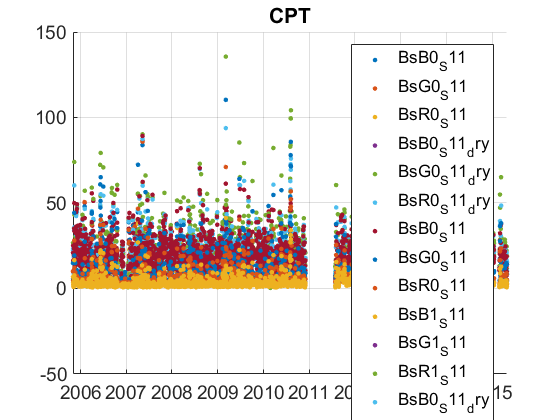

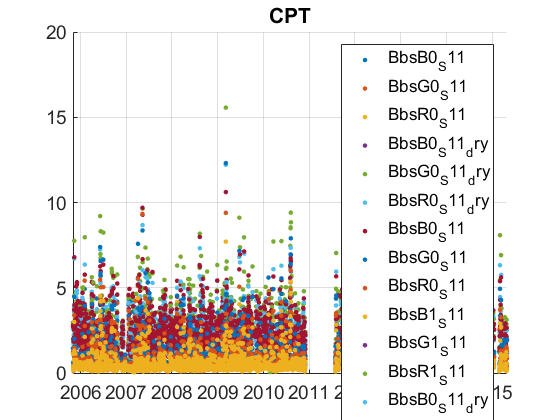

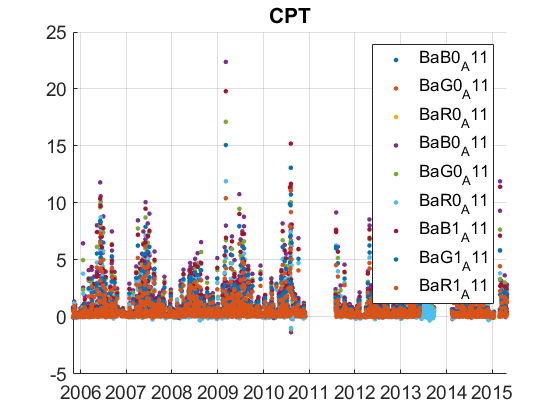

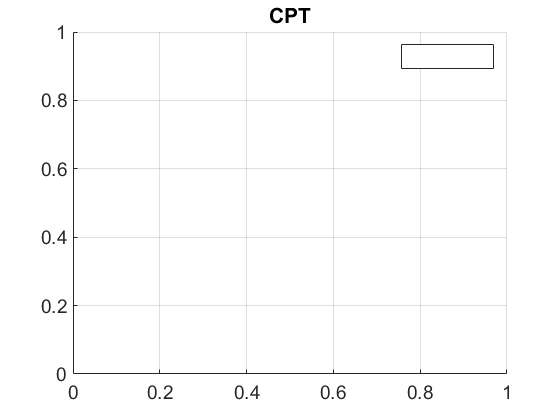

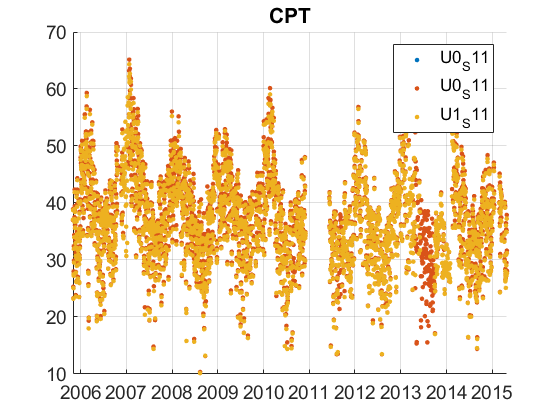

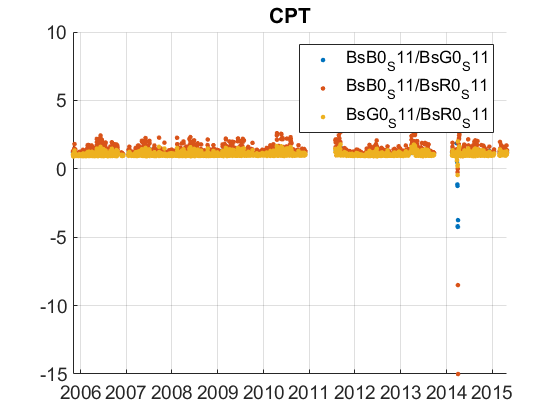

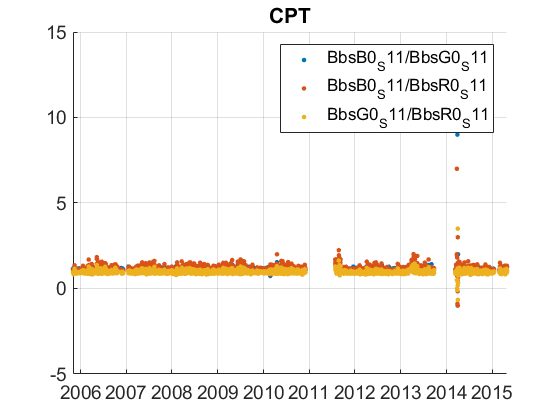

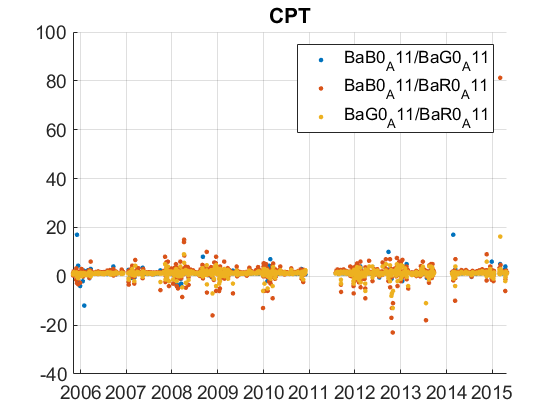

plotFigControl(CPT_rd,CPT_st.name);

% 2 size cut, ok
% sc: ok, no negatives, no seasonal cycle
%abs:  negatives, max in summer
%Abs exponent: clear seasonal cycle

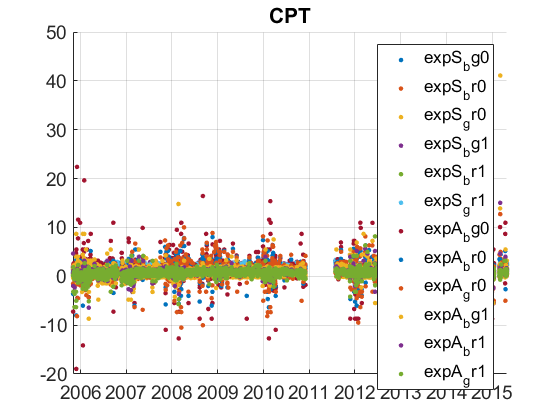

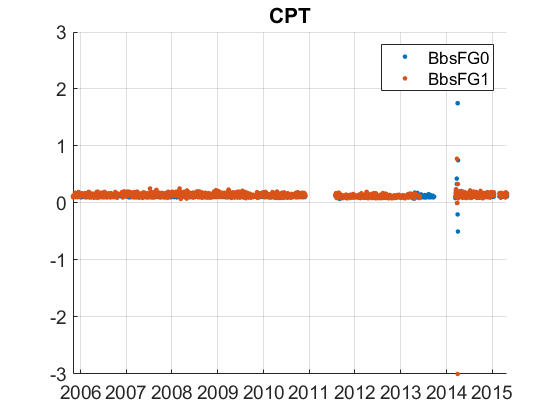

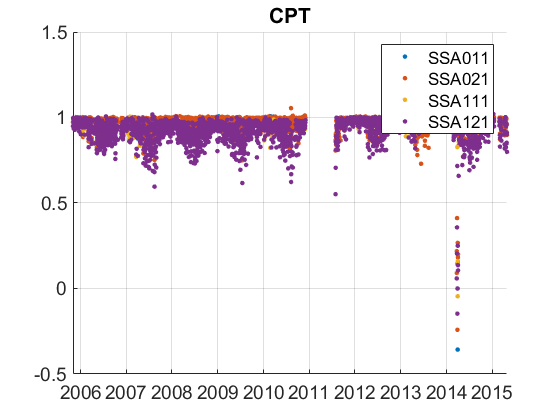

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
lambdaAE7=[370 470 520 590 660 880 950];
CPT_cal=compute_exp_SSA(CPT_rd,lambdaSC, lambdaAE);
plotFigControl_cal(CPT_cal, CPT_st.name);

%problems with g and N data???

%Questions:
%problems:

%Humidity: stable

%scat:I don't know what are the parameter with a g (BsB0g_S11) or with a N (BsB0N_S11)
%scat: OK
%abs: OK
% no question

CPT_tr=CPT_rd;
CPT_tr.y=year(CPT_tr.Time);
% begin at the beginning of a year: 2006
%end: 2014
P=timerange('2006-01-01','2015-01-01');
CPT_tr=CPT_tr(P,:);

% delete BsB0g_S11 and BsB0N_S11, idem for PM1 if available
names=fieldnames(CPT_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_";"N";"Uu";"U1"]) | contains(names,['g','N']) | contains(names,'Q');
N=names(c);
for i=1:length(N)
    CPT_tr.(N{i})=[];
end

%Pm1 problem between August 2011 and June 2013
p1=timerange('2011-08-01','2013-07-01');
names=fieldnames(CPT_tr);
c= contains(names,['1_']) ;
N=names(c);
for i=1:length(N)
    CPT_tr.(N{i})(p1)=NaN;
end

%all other are fine!
%compute new values
CPT_cal2=compute_exp_SSA(CPT_tr,lambdaSC, lambdaAE);
CPT_cal2.SSA0G=CPT_tr.BsG0_S11./(CPT_tr.BsG0_S11+CPT_tr.BaG0_A11);
CPT_cal2.SSA1G=CPT_tr.BsG1_S11./(CPT_tr.BsG1_S11+CPT_tr.BaG1_A11);
CPT_cal2.SSA0G_dry=CPT_tr.BsG0_S11_dry./(CPT_tr.BsG0_S11_dry+CPT_tr.BaG0_A11);%CPT_cal2.SSA1G_dry=CPT_tr.BsG1_S11_dry./(CPT_tr.BsG1_S11_dry+CPT_tr.BaG1_A11);
CPT_cal2.expS_bg0_dry=real(-log(CPT_tr.BsB0_S11_dry./CPT_tr.BsG0_S11_dry)/log(lambdaSC(1)/lambdaSC(2)));
CPT_cal2.expS_bg1_dry=real(-log(CPT_tr.BsB1_S11_dry./CPT_tr.BsG1_S11_dry)/log(lambdaSC(1)/lambdaSC(2)));
CPT_cal2.BbsFG0_dry=CPT_tr.BbsG0_S11_dry./CPT_tr.BsG0_S11_dry;
CPT_cal2.BbsFG1_dry=CPT_tr.BbsG1_S11_dry./CPT_tr.BsG1_S11_dry;
CPT_tr=outerjoin(CPT_tr, CPT_cal2);
%compute U and dry trend

%detele non necessary parameters for the trend analysis:
CPT_tr.BsB0_S11=[];
CPT_tr.BsB1_S11=[];
CPT_tr.BsR0_S11=[];
CPT_tr.BsR1_S11=[];
CPT_tr.BbsB0_S11=[];
CPT_tr.BbsB1_S11=[];
CPT_tr.BbsR0_S11=[];
CPT_tr.BbsR1_S11=[];
CPT_tr.BsB0_S11_dry=[];
CPT_tr.BsB1_S11_dry=[];
CPT_tr.BsR0_S11_dry=[];
CPT_tr.BsR1_S11_dry=[];
CPT_tr.BbsB0_S11_dry=[];
CPT_tr.BbsB1_S11_dry=[];
CPT_tr.BbsR0_S11_dry=[];
CPT_tr.BbsR1_S11_dry=[];
CPT_tr.BaB0_A11=[];
CPT_tr.BaR0_A11=[];
CPT_tr.BaB1_A11=[];
CPT_tr.BaR1_A11=[];
CPT_tr.expA_br0=[];
CPT_tr.expA_gr0=[];
CPT_tr.expA_br1=[];
CPT_tr.expA_gr1=[];
CPT_tr.expS_br0=[];
CPT_tr.expS_gr0=[];
CPT_tr.expS_br1=[];
CPT_tr.expS_gr1=[];
CPT_tr.SSA011=[];
CPT_tr.SSA021=[];
CPT_tr.SSA111=[];
CPT_tr.SSA121=[];

CPT_result= all_trend_STN(CPT_tr,CPT_st); 

CPT_result_D=CPT_result;